# Visualize vehicle trajectories with Birdeye Scope

- First, simulate the vehicles' driving scenario in MOBATSim. The birdeye scope doesn't allow the vehicle to stay on halt. So please set the appropriate scenario and the simulation time, to make sure any vehicle won't stop on the half way.

%startingPoints =    [84 86 15 15 15 15 15 15 15 15];
%destinationPoints = [83 51 14 14  14  14 14 14 14 14];
%maxSpeeds = [7 20 8 10 14 20 10 12 10 10];

          2. ToWorkspace block need to be added to Vehicle 1 and vehicle 2 in Vehicle Kinematic 3DOF Single Track block in "Simulink Models/MOBATSim.slx":

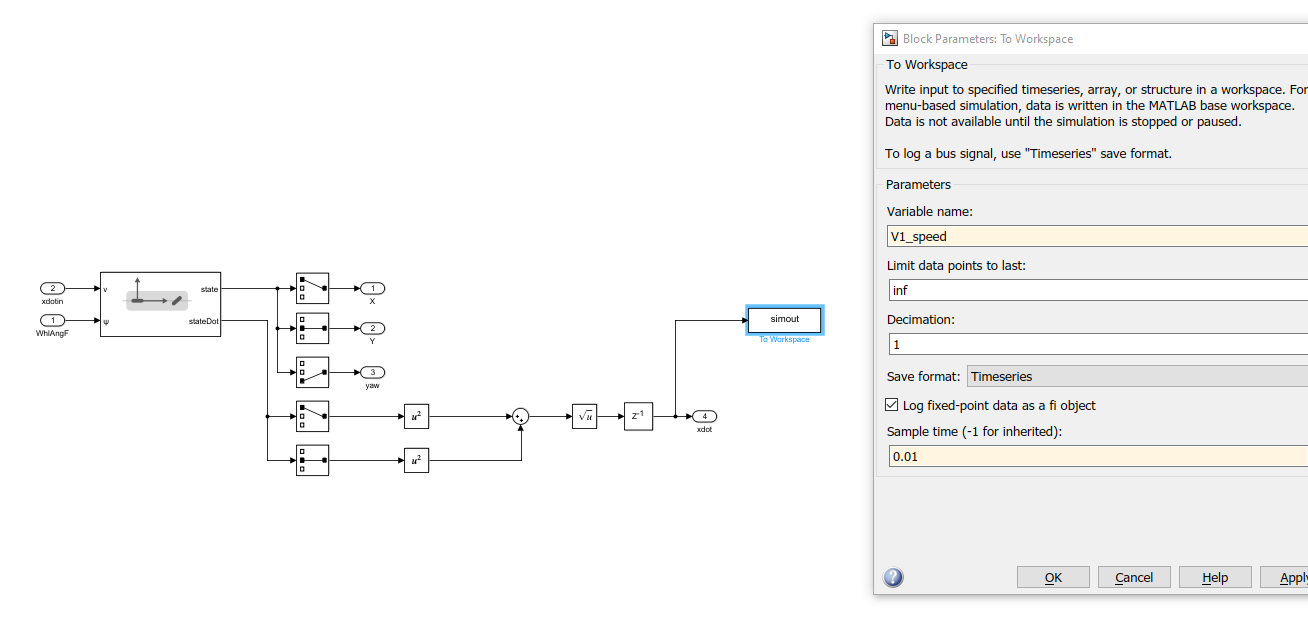

     3.Then run the simulation, stop time is 40s.

    4.After simulation is done, save workspace under the same folder with 'DrivingScenarioDesigner.m' with name 'data'.

    5. Go into 'DrivingScenarioDesigner.m', replace line 597 'temp = evalin('base','ans');' with load('ans.mat');

load('data.mat');
% temp = evalin('base','ans');

Delete all 'temp.'

egoVehicle = vehicle(scenario, ...
    'ClassID', 2, ...
    'Position', [-V2_translation.Data(1,3) -V2_translation.Data(1,1) 0]);
waypoints = [-V2_translation.Data((1:step_length:end),3) -V2_translation.Data((1:step_length:end),1) V2_translation.Data((1:step_length:end),2)];
speed = V2_speed.Data(1:step_length:end);
trajectory(egoVehicle, waypoints, speed);

      6. Next, run "DrivingScenarioDesigner.m" and get a valid "ans" in Comand Window:

ans = 

  drivingScenario with properties:

        SampleTime: 0.0100

          StopTime: Inf

    SimulationTime: 0

         IsRunning: 1

            Actors: [1×2 driving.scenario.Vehicle]

       7.Next, open ScenarioAnimation.slx and Bird's-Eye Scope App.

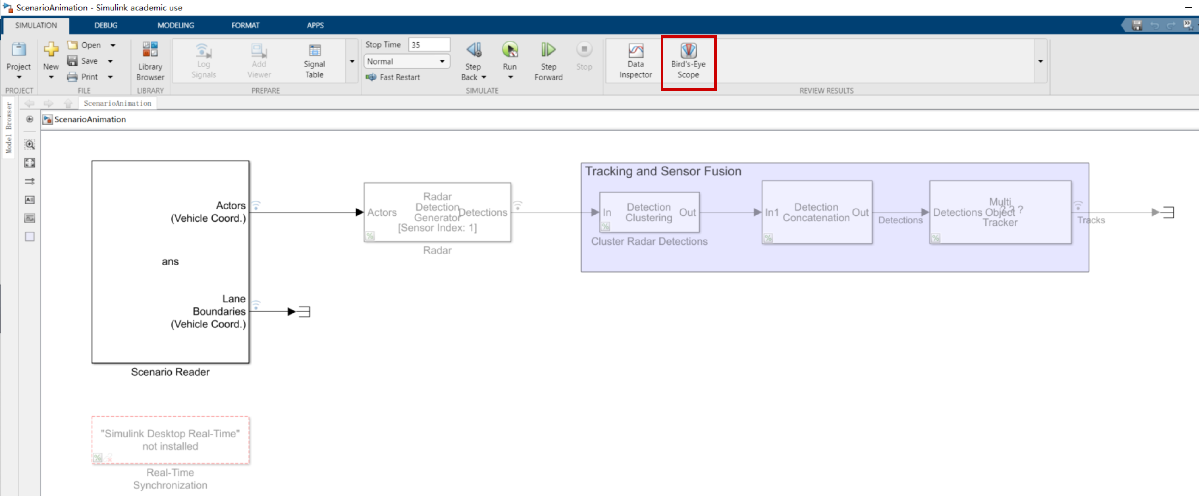

-  click button "Find Signals"

-  clikc button "run" , the trajectories are visualized.

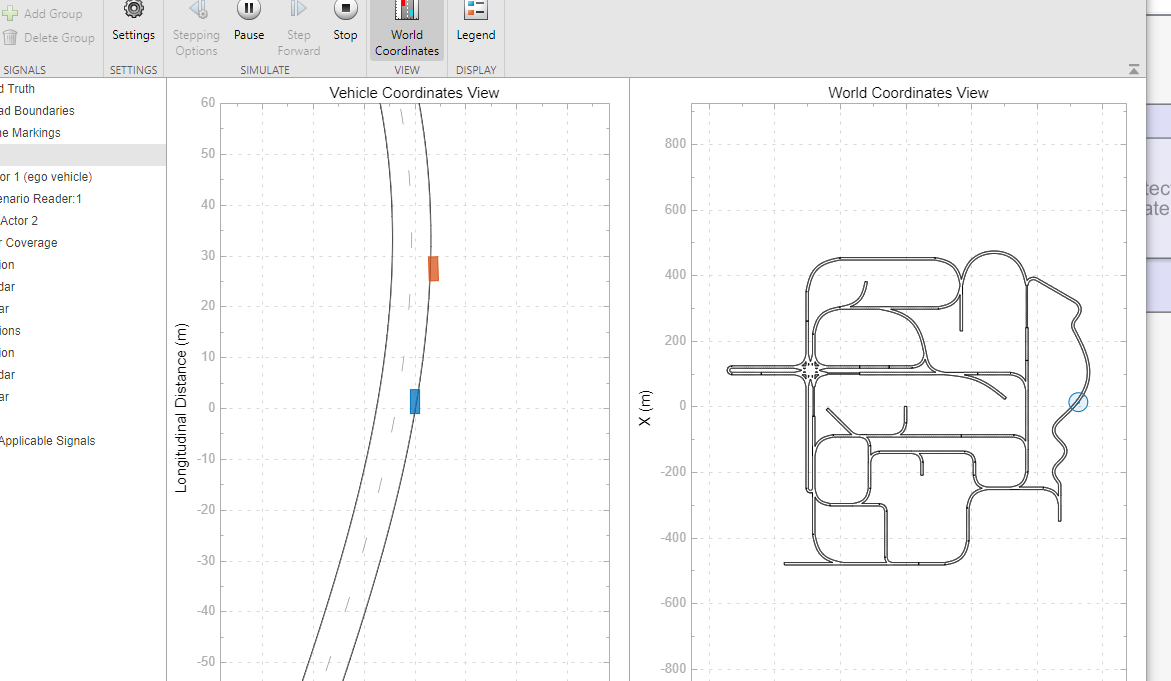

## Or for the simplicity, you can do like this:

- Run the whole MOBATSim project (choose appropriate scenario and simulation time to make sure the vehicles won't stop on the half way)

- After all the data are in the workspace, run "run_Bird_eye_view.m"

- Open Bird's-Eye Scope App

- Click button "Find Signals"

- Click button "run" , the trajectories are visualized.

- if you want to change the ego vehicle, just put the code of the corresponding vehicle to the first place in "DrivingScenarioDesigner.m".